# Figure 6D, 6E, S8E

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A050_data.mat'],'S','settings','allIF');


conditions = settings.conditions

conditions = 20×5 cell array
    {'TAK DMSO'        }    {[2 3 4]}    {[2]}    {[1]}    {[37]}
    {'DMSO DMSO'       }    {[5 6 7]}    {[2]}    {[1]}    {[37]}
    {'TAK DOX'         }    {[2 3 4]}    {[3]}    {[1]}    {[37]}
    {'DMSO DOX'        }    {[5 6 7]}    {[3]}    {[1]}    {[37]}
    {'TAK 1i 20uM'     }    {[2 3 4]}    {[4]}    {[1]}    {[37]}
    {'DMSO 1i 20uM'    }    {[5 6 7]}    {[4]}    {[1]}    {[37]}
    {'TAK 1i 10uM'     }    {[2 3 4]}    {[5]}    {[1]}    {[37]}
    {'DMSO 1i 10uM'    }    {[5 6 7]}    {[5]}    {[1]}    {[37]}
    {'TAK 2i 1uM'      }    {[2 3 4]}    {[6]}    {[1]}    {[37]}
    {'DMSO 2i 1uM'     }    {[5 6 7]}    {[6]}    {[1]}    {[37]}
    {'TAK 1+2i 10+1uM' }    {[2 3 4]}    {[7]}    {[1]}    {[37]}
    {'DMSO 1+2i 10+1uM'}    {[5 6 7]}    {[7]}    {[1]}    {[37]}
    {'TAK 1+2i 20+1uM' }    {[2 3 4]}    {[8]}    {[1]}    {[37]}
    {'DMSO 1+2i 20+1uM'}    {[5 6 7]}    {[8]}    {[1]}    {[37]}
    {'TAK 4/6i'        }    {[2 3 4]}    {[9]} 

framesPerHr = 60/12;
frameDrugAdded = 37;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

6D

conds=[2 4];
colors = [.5 .5 .5;1 .5 .2;.6 .8 .1; 1 .5 .2;.5 .1 1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
linetype = {'-','-','--','--'};
timeGate = [10 20];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
     inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
 
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',2,'linestyle',linetype(i)});
end

ans = 5491

ans = 5985

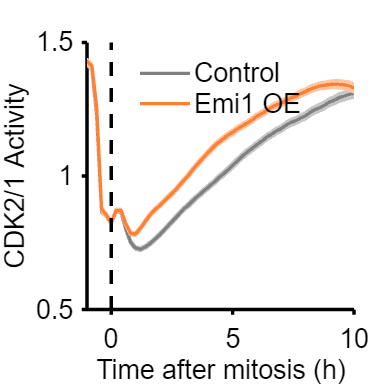


ylabel({'CDK2/1 Activity'});
xlabel('Time after mitosis (h)');
legend('Control','Emi1 OE','box','off','Location','north','fontsize',16);
set(gca,'fontsize',16,'linewidth',2)
xlim([-1 10]); 
ylim([.5 1.5]);
vline([0],'k--')

% hline(1.1,'r--')

% print_pdf(['fig_6d.pdf'])

6E

conds=[2 4];
clear cols
colors = [.5 .5 .5; 1 .5 .2;.5 .1 1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
POI_align = 3;
ally = [];
groups = [];
timeGate = [10 20];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
       inds = ~isnan(S(conds(i)).POI(:,POI_align)) & ~isnan(S(conds(i)).POI(:,1)) & ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
 
sum(inds)



    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));

    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);


end

ans = 3235

ans = 2816

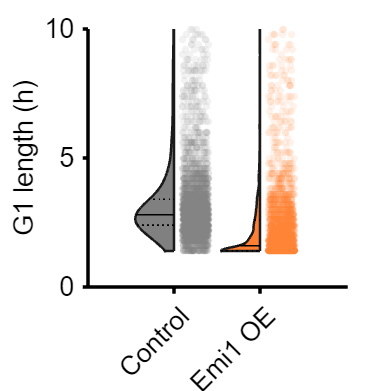




figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


hline(0,'k')
xticklabels({'Control','Emi1 OE','CDC7i','CDC7i + Emi1 OE'})
yticks(0:5:10)
xtickangle(45)
ylim([0 10])
axis square
set(gca,'fontsize',16,'linewidth',2)
set(gca, 'color','white','XColor','black','Ycolor','black')


p=mediantest(ally(groups==1),ally(groups==2))

p = 1.1446e-238


 % print_pdf(['fig_6e.pdf'])


S8E left

conds=[2 4 1 3];
colors = [.5 .5 .5;.6 .8 .1; 1 .5 .2;.5 .1 1;.333 .302 .541;.5 .5 .5; 1 .5 .2;.5 .1 1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
linetype = {'-','-','--','--'};
timeGate = [10 20];

figure('unit','inches','position',[0 0 4 6])
nexttile
hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
   sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
    plot(x,f,'Color',colors(i,:),'LineStyle',linetype(i),'linewidth',2);

end

ans = 5491

ans = 5985

ans = 2668

ans = 2609

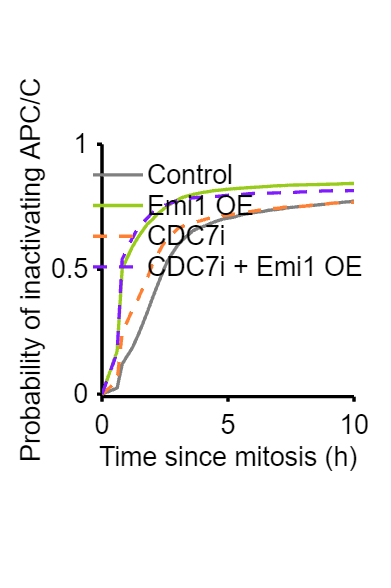



axis square
legend('Control','Emi1 OE','CDC7i','CDC7i + Emi1 OE','Box','off','Location','north','FontSize',16);
xlim([0 10]); 
xticks(0:5:10)
ylim([-.01 1]);
set(gca,'fontsize',16,'linewidth',2)
xlabel('Time since mitosis (h)','FontSize',16)
ylabel('Probability of inactivating APC/C','FontSize',16)
hold on

% print_pdf(['Fig_S8E_left.pdf'])


S8E middle

conds=[1 3];
colors = [.6 .8 .1;.5 .1 1;1 .5 .2;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
POI_align = 3;
ally = [];
groups = [];
timeGate = [10 20];

 clear cols
for i=1:length(conds)
    c = conds(i);
    data = S(c);
       inds = ~isnan(S(conds(i)).POI(:,POI_align)) & ~isnan(S(conds(i)).POI(:,1)) & ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
 
sum(inds)

    


    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 
end

ans = 1220

ans = 1188

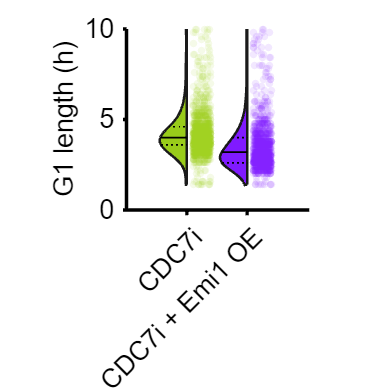





figure('Units', 'Inches', 'Position', [0, 0, 6, 6])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


hline(0,'k')
xticklabels({'CDC7i','CDC7i + Emi1 OE'})
yticks(0:5:10)
xtickangle(45)
ylim([0 10])
axis square
set(gca,'fontsize',16,'linewidth',2)
set(gca, 'color','white','XColor','black','Ycolor','black')



p=mediantest(ally(groups==1),ally(groups==2))

p = 6.1230e-60


 % print_pdf(['fig_S8E_middle.pdf'])

S8E right

conds=[2 4 1 3];
colors = [.5 .5 .5;.6 .8 .1; 1 .5 .2;.5 .1 1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
linetype = {'-','-','--','--'};
timeGate = [10 20];

figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
          inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
       S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',2,'linestyle',linetype(i)});
end

ans = 3235

ans = 2816

ans = 1220

ans = 1188

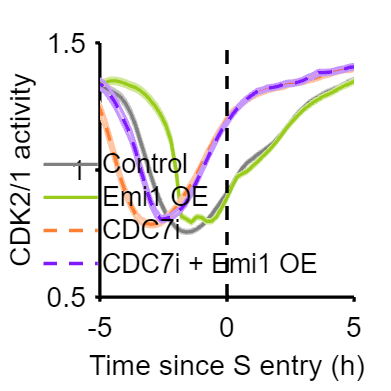


ylabel({'CDK2/1 activity'});xlabel('Time since S entry (h)');
legend('Control','Emi1 OE','CDC7i','CDC7i + Emi1 OE','box','off','Location','south','fontsize',16);
set(gca,'fontsize',17,'linewidth',2)
xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')


 % print_pdf(['Fig_S8E_right.pdf'])